# **SS - lab S6 - Zeic Beniamin**

**Exercise 1**

Compute the autocorrelation function for the signal:


$$x\left(t\right)=A\;\sin \left(\omega_0 \;t+\varphi \right)$$


We assume the signal starts at time t=0. We write the autocorrelation function of the given singal, and then we compute it in a code cell below.


$$\varphi_x \left(\tau \right)=\frac{1}{T_0 }A^2 \int_0^{T_0 } \sin \left(\omega_0 \left(t-\tau \right)+\varphi \right)\;\sin \left(\omega_0 \;t+\varphi \right)\;\textrm{dt}$$


syms t w0 tau phi A
% Compute the period of the signal
T0 = 2*pi/w0;
% Compute the autocorrelation function symbolically
acorr = 1/T0 * A*A * int(sin(w0*(t-tau) + phi)*sin(w0*t + phi), t, 0, T0)

**Exercise 2**

a. Write a function for computing the autocorrelation function.

b. Generate a discrete sinusoidal singal in Matlab, with period 64 and magnitude 1

c. Add white noise.

d. Use the function written at point a to compute the autocorrelation of the noisy signal x[n]

e. Use Matlab to plot the signal x[n] and its autocorrelation function. Plot the autocorrelation for different amplitudes of the noise and estimate (from the graph) the period of the original signal

t = linspace(1,300,500);
% Periodic sinusoidal, with period 64, magnitude 1
signal = @(n)(sin(2*pi*n/64));
response = signal(t);
% Add noise over the signal

$$acorr = \frac{A^{2}\,\cos\left(\tau \,w_{0}\right)}{2}$$

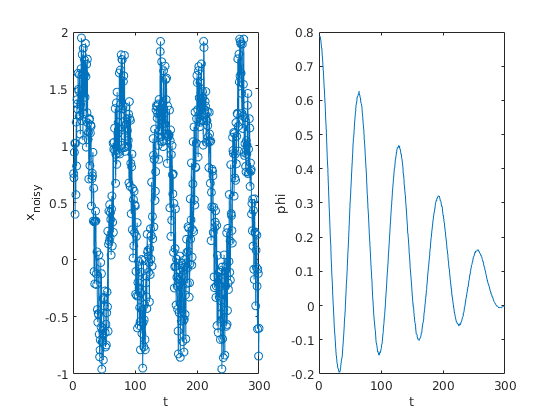

noisy1 = response + rand(1, length(t));
noisy2 = response + 2 * rand(1, length(t));
noisy3 = response + 3 * rand(1, length(t));
% Compute the results
result1 = autocorrelation(noisy1, length(t));
result2 = autocorrelation(noisy2, length(t));
result3 = autocorrelation(noisy3, length(t));

figure
title("Noise amplitude = 1")
subplot(1,2,1)
plot(t, noisy1, '-o');
ylabel("x_{noisy}")
xlabel("t")
subplot(1,2,2)
plot(t, result1)
ylabel("phi")
xlabel("t")

figure
subplot(1,2,1)
plot(t, noisy2, '-o');
ylabel("x_{noisy}")
xlabel("t")
subplot(1,2,2)
plot(t, result2)
ylabel("phi")
xlabel("t")



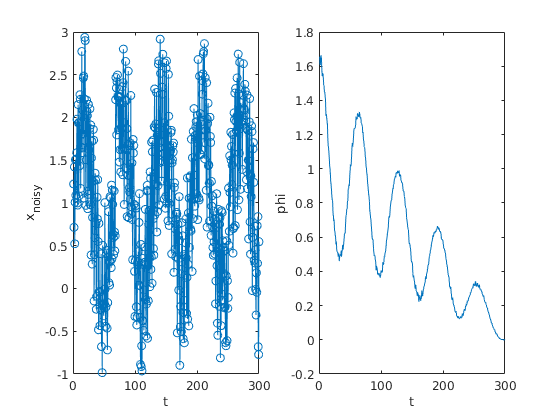

figure
title("Noise amplitude = 3")
subplot(1,2,1)
plot(t, noisy3, '-o');
ylabel("x_{noisy}")
xlabel("t")
subplot(1,2,2)
plot(t, result3)
ylabel("phi")
xlabel("t")

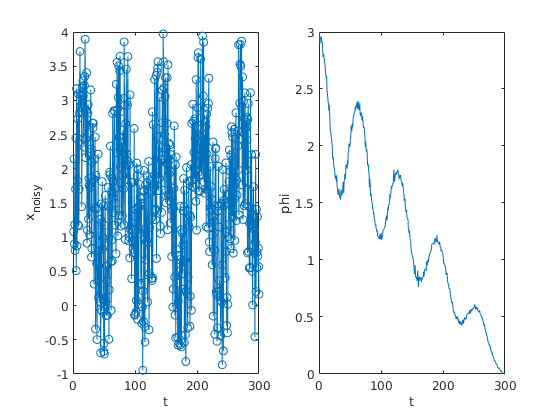

function res = autocorrelation(xsignal, M)
    % Take n as the number of samples of the signal
    N = length(xsignal);
    
    % Calculate the sum for every n
    for i=1:N
        sum = 0;
        
        for k=1:M
            if (k-i > 0)

                sum = sum + xsignal(k)*xsignal(k-i);
            end
           
        end
        % Store the result for the i-th iteration
        res(i) = sum/M;
    end
end